# X-ray and Soft-proton Energy Spectra

clear variables;
x_min= 1; %keV
nEnsemble=256;
nCountRate = 1000; %particles per second
nSamples = 10;
x = 1:100; %1-100 keV
dim = [1,nSamples*nCountRate];

energyMin = 1; %keV
energyMax = 100; %keV
nEnergyBins = 100; 
QE = 0.5; % Decrease in X-ray counting efficiency due to filter
deltaE = 30; %keV Decrease in SP mean energy due to filter

## No filter


% Defining PDF for Soft-protons
alpha = 1.01; %Power law of the soft protons
xmin = 1; % 1 keV
pdf_plaw = ((alpha-1)./x_min).*(x./x_min).^-alpha;
% Defining PFD for X-ray 
mean = 10; %keV
sigma = 3; %keV

xrayCCD1 = normrnd(mean,sigma,dim);
SPCCD1 = randpdf(pdf_plaw,x,dim);


## With Filter


% PDF for soft protons after filter
x2 = x(1):round(x(end)+deltaE);  
pdf_plaw2 = ((alpha-1)./x_min).*(x2./x_min).^-alpha;


% x2=x+deltaE;
% pdf_plaw1 = ((alpha-1)./x_min).*((x1)./x_min).^-alpha;
% PDF for X-ray after fiter
SPCCD2 = randpdf(pdf_plaw2,x2,dim)-normrnd(deltaE,sigma,dim);
SPCCD2(SPCCD2<0)=nan;
xrayCCD2 = normrnd(mean,sigma,[1, round(nSamples*nCountRate*QE)]);

## Binning

energyBins = linspace(energyMin,energyMax,nEnergyBins);

SPCCD1Hist   = hist(SPCCD1(:),energyBins);
xrayCCD1Hist = hist(xrayCCD1(:),energyBins);
CCD1Hist     = SPCCD1Hist+xrayCCD1Hist;

SPCCD2Hist   = hist(SPCCD2(:),energyBins);
xrayCCD2Hist = hist(xrayCCD2(:),energyBins);
CCD2Hist     = SPCCD2Hist + xrayCCD2Hist;


## Plotting the distribution

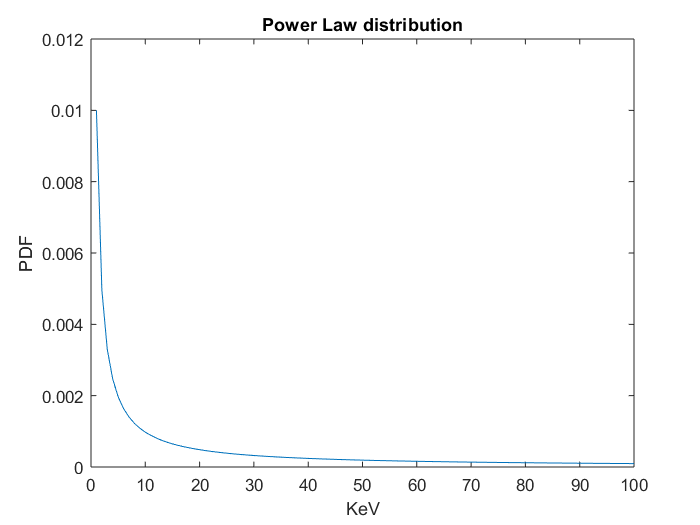

figure;
plot(x,pdf_plaw); 
title('Power Law distribution'); xlabel('KeV');ylabel('PDF');

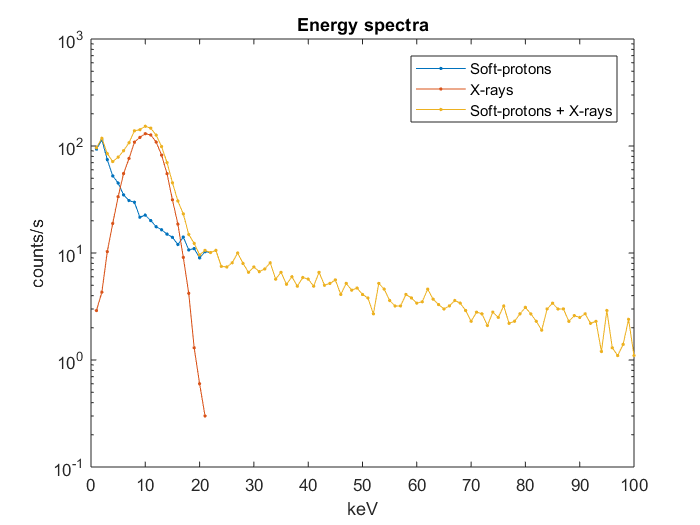


figure; plot(energyBins,SPCCD1Hist/nSamples,'.-'); title('Energy spectra');
xlabel('keV');
ylabel('counts/s');
hold on;
plot(energyBins,xrayCCD1Hist/nSamples,'.-');
hold on;
plot(energyBins,(CCD1Hist)./nSamples,'.-');
legend('Soft-protons','X-rays','Soft-protons + X-rays');
set(gca,'YScale','log');

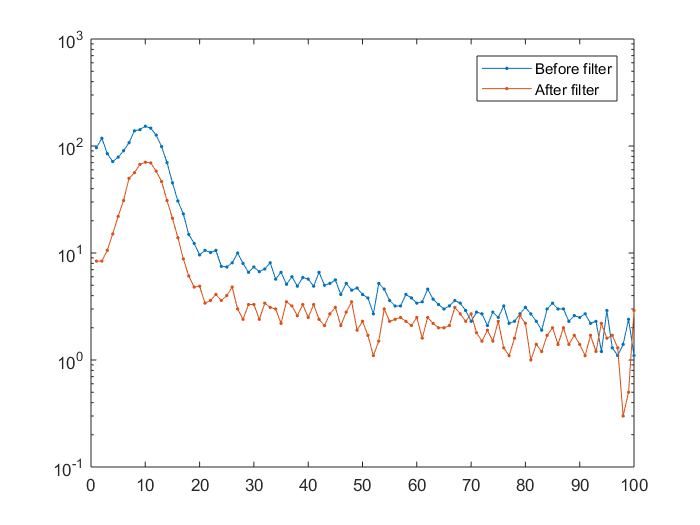


figure;
plot(energyBins,CCD1Hist./nSamples,'.-');
hold on;
plot(energyBins,CCD2Hist./nSamples,'.-');
legend('Before filter','After filter');
set(gca,'YScale','log');

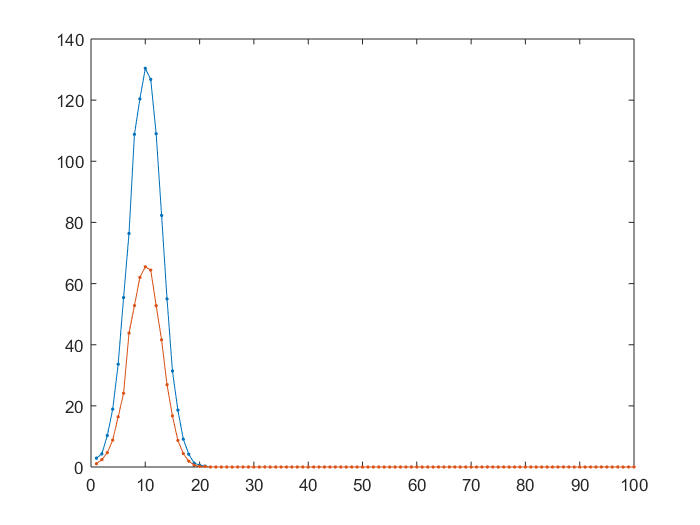


figure;
plot(energyBins,xrayCCD1Hist./nSamples,'.-'); hold on;
plot(energyBins,xrayCCD2Hist./nSamples,'.-');

## Functions

 Non linear fitter function

function outputTemp = run_nonlin_fitter(lag,data,stdDeviation,inputNLR0,options)
    outputTemp = lsqnonlin(@F,inputNLR0,[],[],options)';
% Creating the function handle F(x): (model-data)./standard_deviation
    function y = F(inputNLR)
        y = (autocorrelation_model...
   (inputNLR(1),inputNLR(2),inputNLR(4),inputNLR(3),lag)-data)./stdDeviation;
    end
end
% Defining the model ACF
function RmArray = autocorrelation_model(N,A,fWidth,omegaDoppler,lag)
       RmArray =N*double(lag==0) + A.*exp(-abs(lag).*fWidth).*exp(-1i*omegaDoppler.*lag);
end

function x=randpdf(p,px,dim)
% RANDPDF
%   Random numbers from a user defined distribution
%
% SYNTAX:
%   x = randpdf(p, px, dim)
%       randpdf(p, px, dim)
% 
% INPUT:
%   p   - probability density,
%   px  - values for probability density,
%   dim - dimension for the output matrix.
%
% OUTPUT:
%   x   - random numbers. Run function without output for some plots.
%
% DESCRIPTION:
%   x = randpdf(p, px, dim) returns the matrix of random numbers from
%   probability density distribution defined in p and px. p are the density
%   (the y axis) and px are the value (the x axis) of the pdf. p and px
%   must be of the same length.
%   dim define the output matrix dimensions, for example dim=[100 3] define
%   the 100x3 two dimensional matrix with 300 random numbers.
%
%   REMEMBER: This is not a realy random number generator but only
%   some kind of transformation of uniformly distributed pseudorandom 
%   numbers to desired pdf!
% 
% EXAMPLE 1:
%   Generation of normal distributed random numbers. This is not typical
%   normal distribution because is limited from the left and right side,
%   i.e. 0 < px < 80 .
%   
%   px=0:80;
%   p=1./(10*sqrt(2*pi))*exp((-(px-40).^2)./(2*10^2));
%   randpdf(p,px,[10000,1])
%
%
% EXAMPLE 2:
%   Generation using user defined pdf.
%   
%   px=[1 2 3 4 5 6 7 8 9];
%   p= [0 1 3 0 0 4 5 4 0];
%   randpdf(p,px,[50000,1])

% By Adam Niesony, Opole University of Technology, Poland

% check the number of input
narginchk(3, 3)

% vectorization and normalization of the input pdf
px=px(:);
p=p(:)./trapz(px,p(:));

% interpolation of the input pdf for better integration
% in my opinion 10000 point is sufficient...
pxi=[linspace(min(px),max(px),10000)]';
pi=interp1(px,p,pxi,'linear');

% computing the cumulative distribution function for input pdf
cdfp = cumtrapz(pxi,pi);

% finding the parts of cdf parallel to the X axis 
ind=[true; not(diff(cdfp)==0)];

% and cut out the parts
cdfp=cdfp(ind);
pi=pi(ind);
pxi=pxi(ind);

% generating the uniform distributed random numbers
uniformDistNum=rand(dim);

% and distributing the numbers using cdf from input pdf
userDistNum=interp1(cdfp,pxi,uniformDistNum(:)','linear');

% making graphs if no output exists
if nargout==0
    subplot(3,4,[1 2 5 6])
    [n,xout]=hist(userDistNum,50);
    n=n./sum(n)./(xout(2)-xout(1));
    bar(xout,n)
    hold on
    plot(pxi, pi./trapz(pxi,pi),'r')
    hold off
    legend('pdf from generated numbers','input pdf')

    subplot(3,4,[3 4 7 8])
    plot(pxi, cdfp,'g')
    ylim([0 1])
    legend('cdf from input pdf')

    subplot(3,4,[9:12])
    plot(userDistNum)
    legend('generated numbers')
else
    x=reshape(userDistNum,dim);
end
end